# Mars Laser Orbiter Altimeter (MOLA) topography

The code for manupulating the mars topography data was modified from the following MATLAB FileExchange entry

[https://www.mathworks.com/matlabcentral/fileexchange/13444-using-data-from-mola](https://www.mathworks.com/matlabcentral/fileexchange/13444-using-data-from-mola) 

It looks like the location of the data has changed to the following address

[https://pds-geosciences.wustl.edu/mgs/mgs-m-mola-5-megdr-l3-v1/mgsl_300x/meg016/](https://pds-geosciences.wustl.edu/mgs/mgs-m-mola-5-megdr-l3-v1/mgsl_300x/meg016/)

The Matlab code for the download does not seem to work for me, but you can just click the file

[`megt90n000eb.img`](https://pds-geosciences.wustl.edu/mgs/mgs-m-mola-5-megdr-l3-v1/mgsl_300x/meg016/megt90n000eb.img)

to download it manually to your computer. I have also uploaded it to the class website. Once this file is in the same directory as this LiveScript you can load the data with the following code.

% Read in the file.
resolution = 16;
filename = 'megt90n000eb.img';
f = fopen(filename,'r','ieee-be');
el = fread(f,[360*resolution Inf],'int16')'; % this is the elevation data
fclose(f);

% Down-sample the data.
el = el(1:4:end,1:4:end);
resolution = resolution/4;
disp 'data loaded'

data loaded


This can then be plotted in a variety of ways that look nice but are not very useful for our purposes. I don't understand the details of these functions bu they part of the MATLAB Mapping Toolbox. Note that the map is upside down!

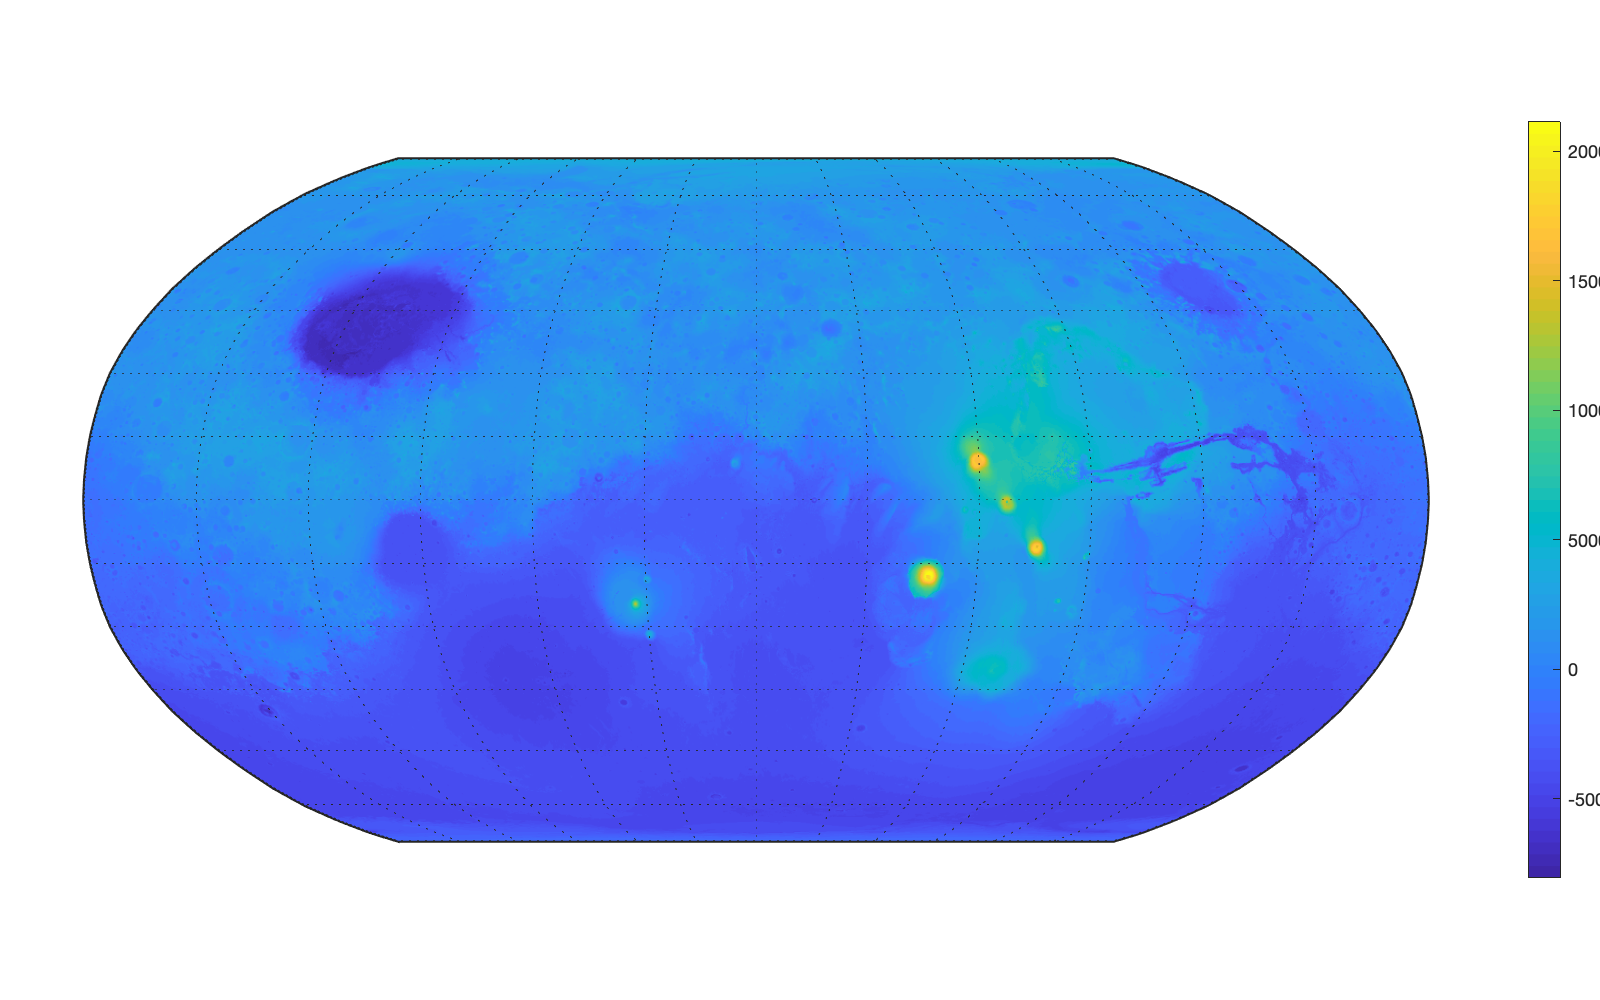

figure('position',[10 10 800 500])
axesm robinson
meshm(el,[resolution 90 -180],size(el));
framem on
gridm on
axis off
set(gca,'position',[0 0 1 1])
colorbar

The topography data can also be plotted on the sphere as follows 

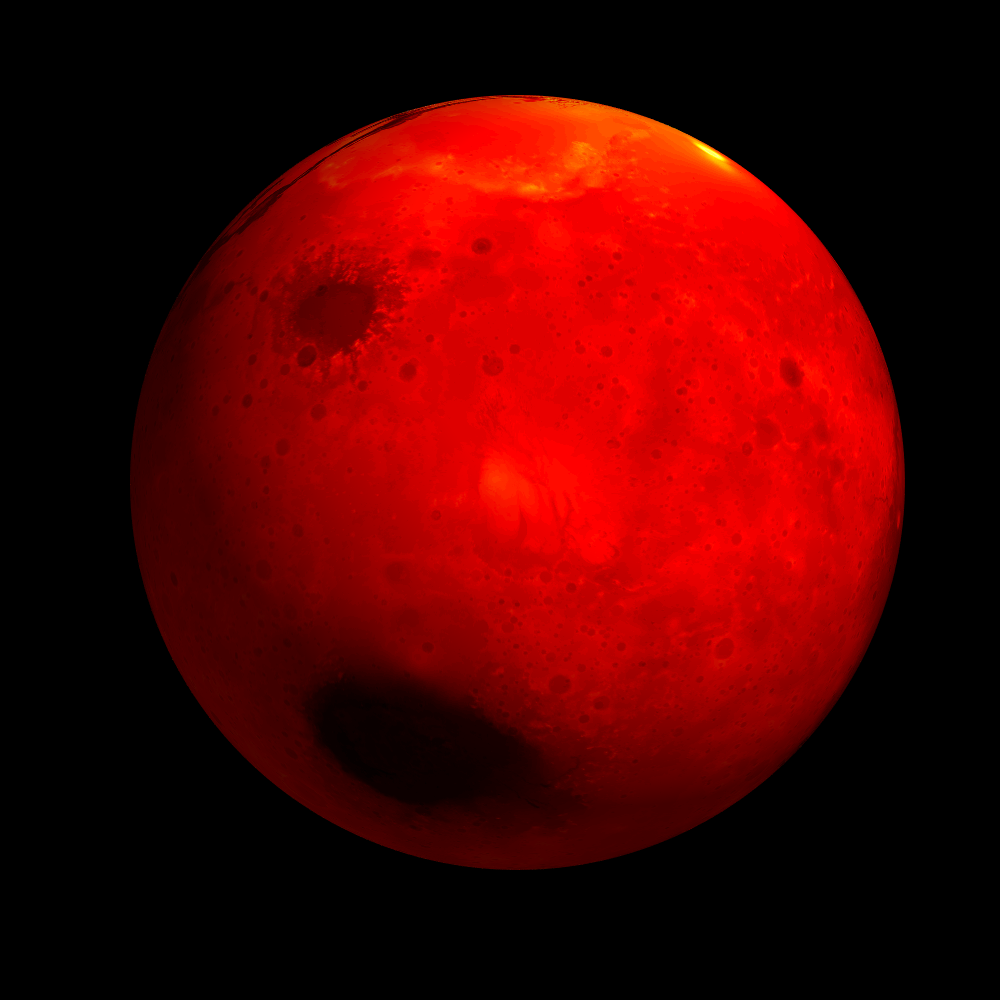

figure('position',[10 10 500 500])
axesm globe
meshm(el,[resolution 90 -180],size(el));
colormap(hot)
axis off vis3d
view(2)
shading interp
material([0.3 1 0])
camlight
set(gcf,'color','black')

Pretty but we need to get this into a format that is compatible with our mesh.

## Making the data useful for our purposes

What we need from this are the contours of the dichotomy boundary and the two large impact basins in the highlinds, Hellas planita and Argyre planita so we can use them as boundaries for our domain. First we make our selves $\theta$ and $\phi$ matrices with meshgrid that matsch the data resolution. 

[Ntheta,Nphi] = size(el);
theta = linspace(0,pi,Ntheta);
phi = linspace(0,2*pi,Nphi);
[Theta,Phi] = meshgrid(theta,phi);


Unfortunately the topodate is not stored so it matches with internal matlab logic so we need to voodo transposes and flips.

mars_topo = fliplr(el');

Then we can plot any elevation contour we want

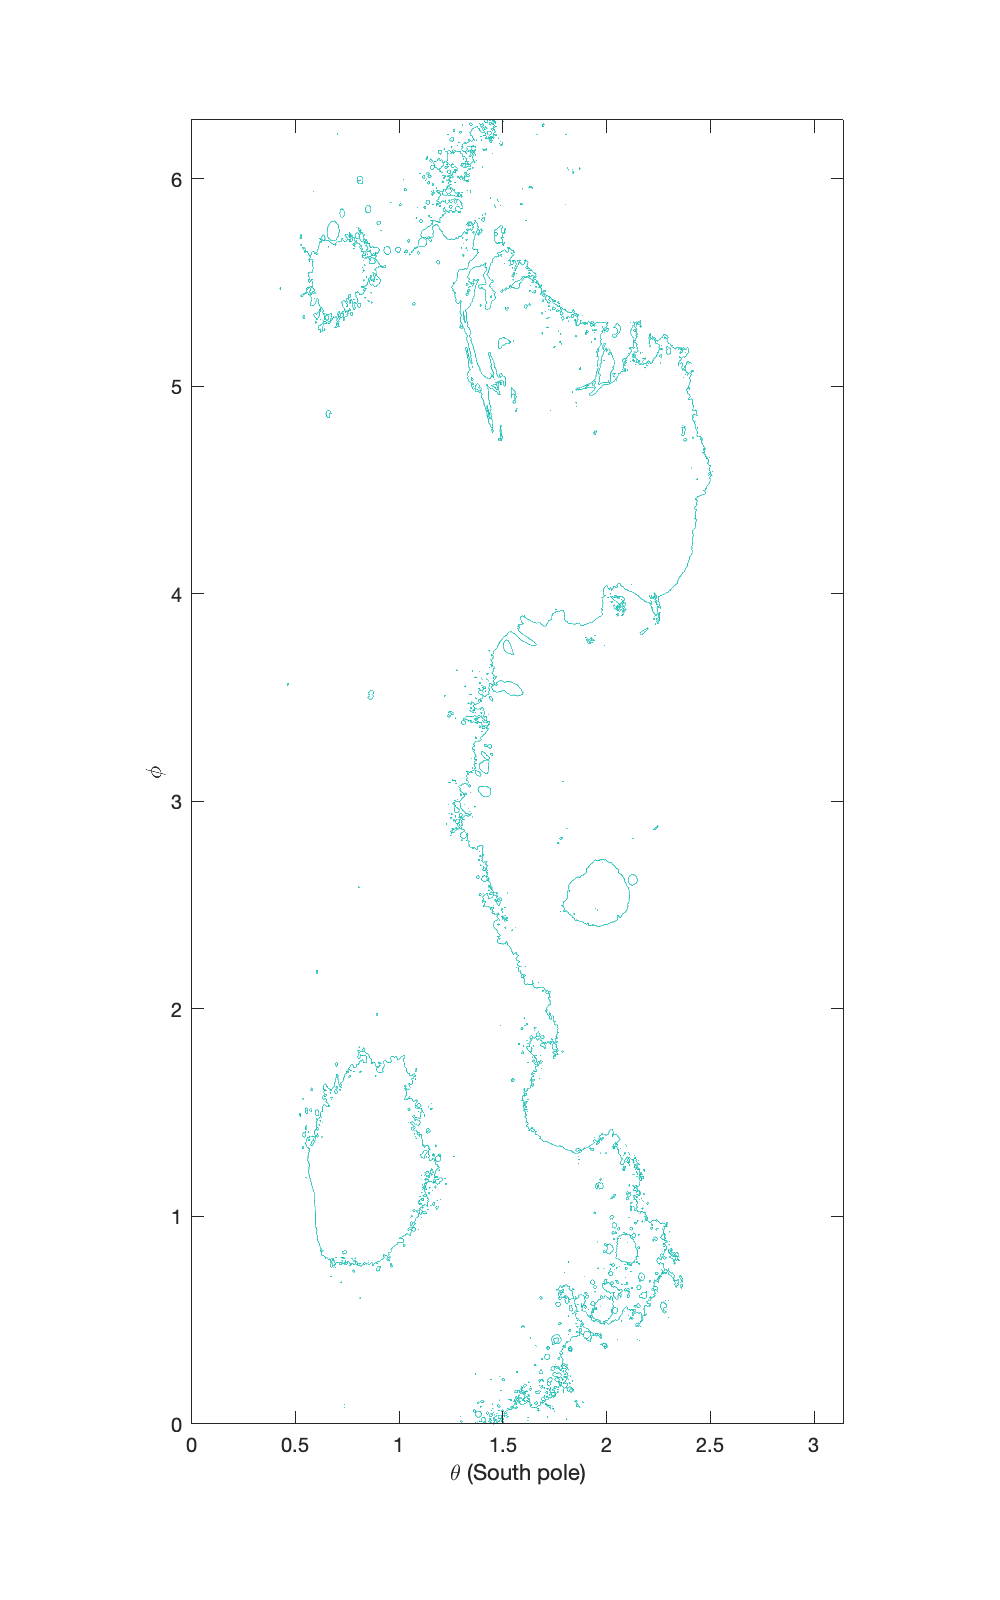

figure('position',[10 10 500 800])
[C,h] = contour(Theta,Phi,mars_topo,-1000*[1 1]); hold on
xlabel '\theta (South pole)'
ylabel '\phi'
axis equal 
xlim([0 pi]), ylim([0 2*pi])

### Extracting individual contours

The contour function outputs a two-row matrix `C` that contains the information about all contourlines. Looking at the plot we see that there are many separate contours. To use them we need to extract the right ones individually. Let's take a look at the beginning of `C`.

[row,col] = size(C)

row = 2

col = 25869

C(:,1:10)

ans = 	1.0e+03 *

   -1.0000    0.0014    0.0014    0.0014    0.0014    0.0014   -1.0000    0.0014    0.0014    0.0014
    0.0050         0    0.0000    0.0000    0.0000         0    0.0060         0    0.0000    0.0000


The fist colum contains the elevation of the contour in C(1,1) = -1000 and the length of the first contour C(2,1) = 5. Folloing this first colum the following 5 columns contain the x-data in the first row and the y-data in the second row. The in the 7th row C(:,7) contains the information about the second contour. The contour elevation is C(1,7) = -1000 and the length of the contour is C(2,7) = 6. All the other contours follow in the same fashion. Hence we can extract the individual contours into a structure as follows.

## Extract contours

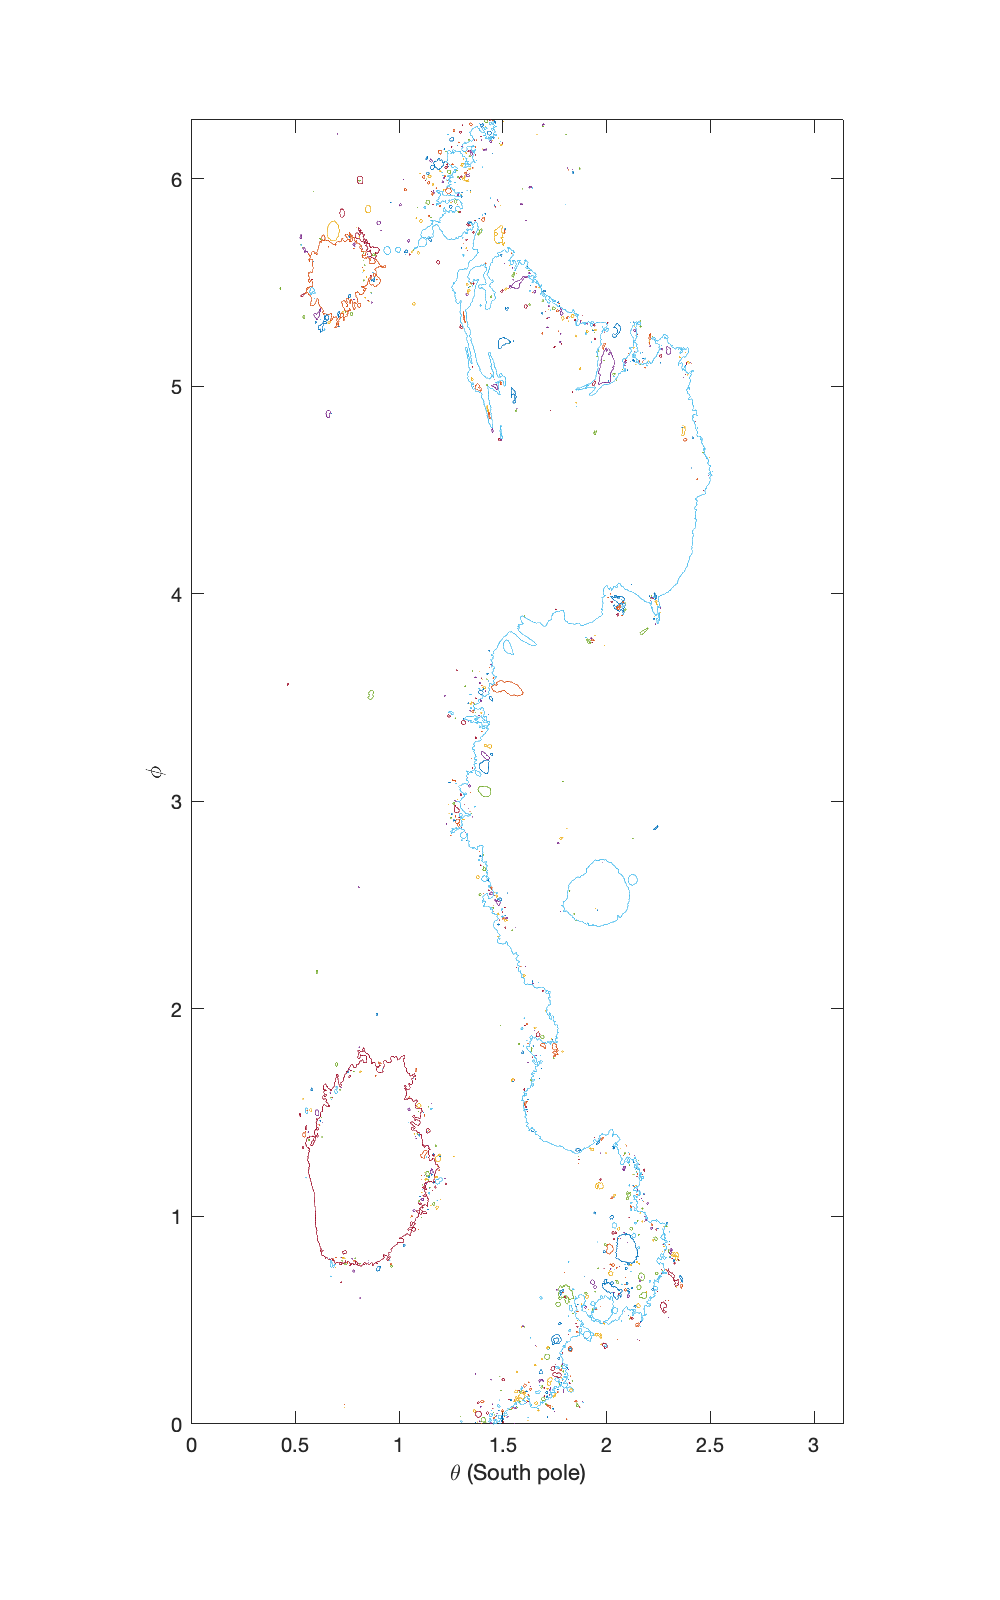


k=1; i = 1;
figure('position',[10 10 500 800])
while k <= col
    len = C(2,k);
    x = C(1,k+1:k+len);
    y = C(2,k+1:k+len);
    plot(x,y), hold on
    cont(i).x = x';
    cont(i).y = y';
    cont(i).N = len;
    Nvec(i) = len;
    k = k+1+len;
    i = i+1;
    plot(x,y), hold on
end
xlabel '\theta (South pole)'
ylabel '\phi'
axis equal 
xlim([0 pi]), ylim([0 2*pi])

% 
[Nsort,i_sort] = sort(Nvec,'descend');
cont = cont(i_sort);
length(cont)

ans = 1433

The structure cont contains all 1433 individual contours which are shown in different colours in the figure. Naturaly the longest contours are those of the biggest structures. Because we have sorted the structure by decreasing size, the first three will be the dichotomy, Hellas and Argyre.

For this particular elevation Hellas has a longer contour than Argyre, but for higher elevations the contour of Argyre becomes very scalloped and actually becomes longer than Hellas so you simply have to check.

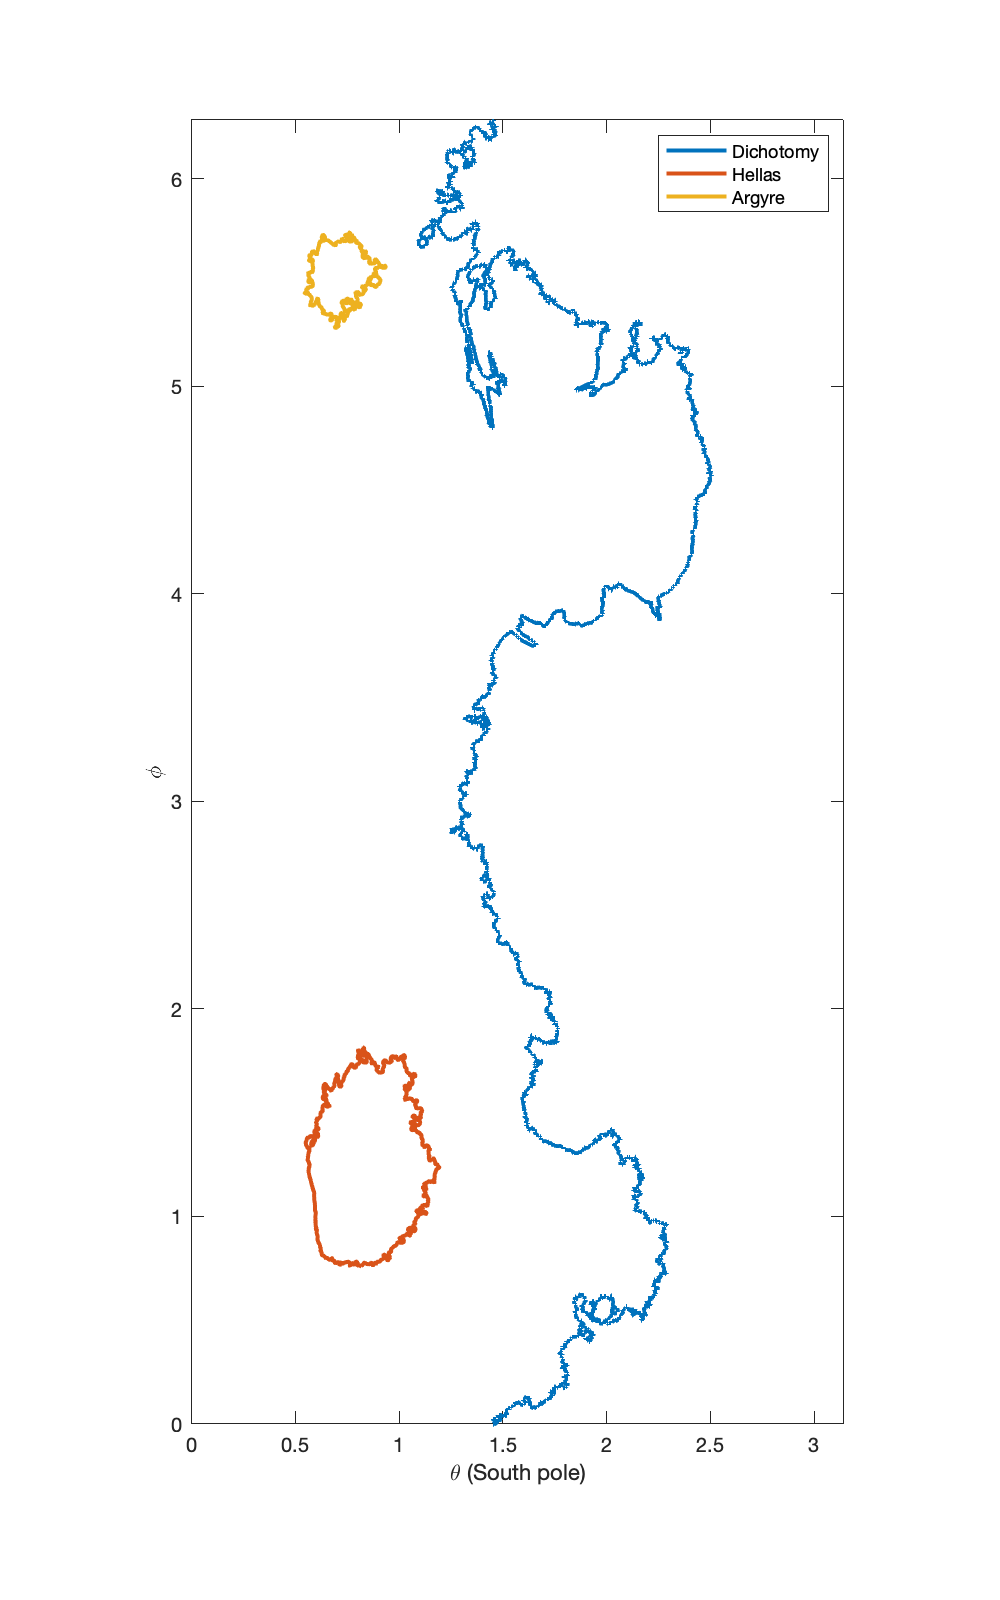

dichotomy.x = cont(1).x;
dichotomy.y = cont(1).y;

hellas.x = cont(2).x;
hellas.y = cont(2).y;

argyre.x = cont(3).x;
argyre.y = cont(3).y;

figure('position',[10 10 500 800])
plot(dichotomy.x,dichotomy.y,'linewidth',2), hold on
plot(hellas.x,hellas.y,'linewidth',2)
plot(argyre.x,argyre.y,'linewidth',2)
xlabel '\theta (South pole)'
ylabel '\phi'
axis equal 
xlim([0 pi]), ylim([0 2*pi])
legend('Dichotomy','Hellas','Argyre')

If you were interested in adding other smaller features, you have to hand pick them from the structure containing the contours. Anything you can see at this resolution will be amongst the fist few contours. Most of the coutours are tiny little circles from from local extrema along some of the larger boundaries.

### Generating the computational domain

Suppose we are using the following somewhat corse computational grid

Grid.xmin = 0; Grid.xmax = pi;   Grid.Nx = 25*6;
Grid.ymin = 0; Grid.ymax = 2*pi; Grid.Ny = 50*6;
Grid = build_grid(Grid);

Then we also need a simple cartesian divergence matrix for the mash connectivity and the locations of the grid points

[Dref,G,I] = build_ops(Grid);
[Xc,Yc] = meshgrid(Grid.xc,Grid.yc);

Hellas and Argyre are close contours and we can use the function inpolygon.m to ontain the dof

% Hellas
dof_hellas = Grid.dof(inpolygon(Xc(:),Yc(:),hellas.x,hellas.y));
dof_f_hellas = find_faces(dof_hellas,Dref,Grid);
[X_f_hellas,Y_f_hellas] = comp_face_coords(dof_f_hellas,Grid);

% Argyre
dof_argyre = Grid.dof(inpolygon(Xc(:),Yc(:),argyre.x,argyre.y));
dof_f_argyre = find_faces(dof_argyre,Dref,Grid);
[X_f_argyre,Y_f_argyre] = comp_face_coords(dof_f_argyre,Grid);

Now we can plot the actual contour and our dicrete approximation

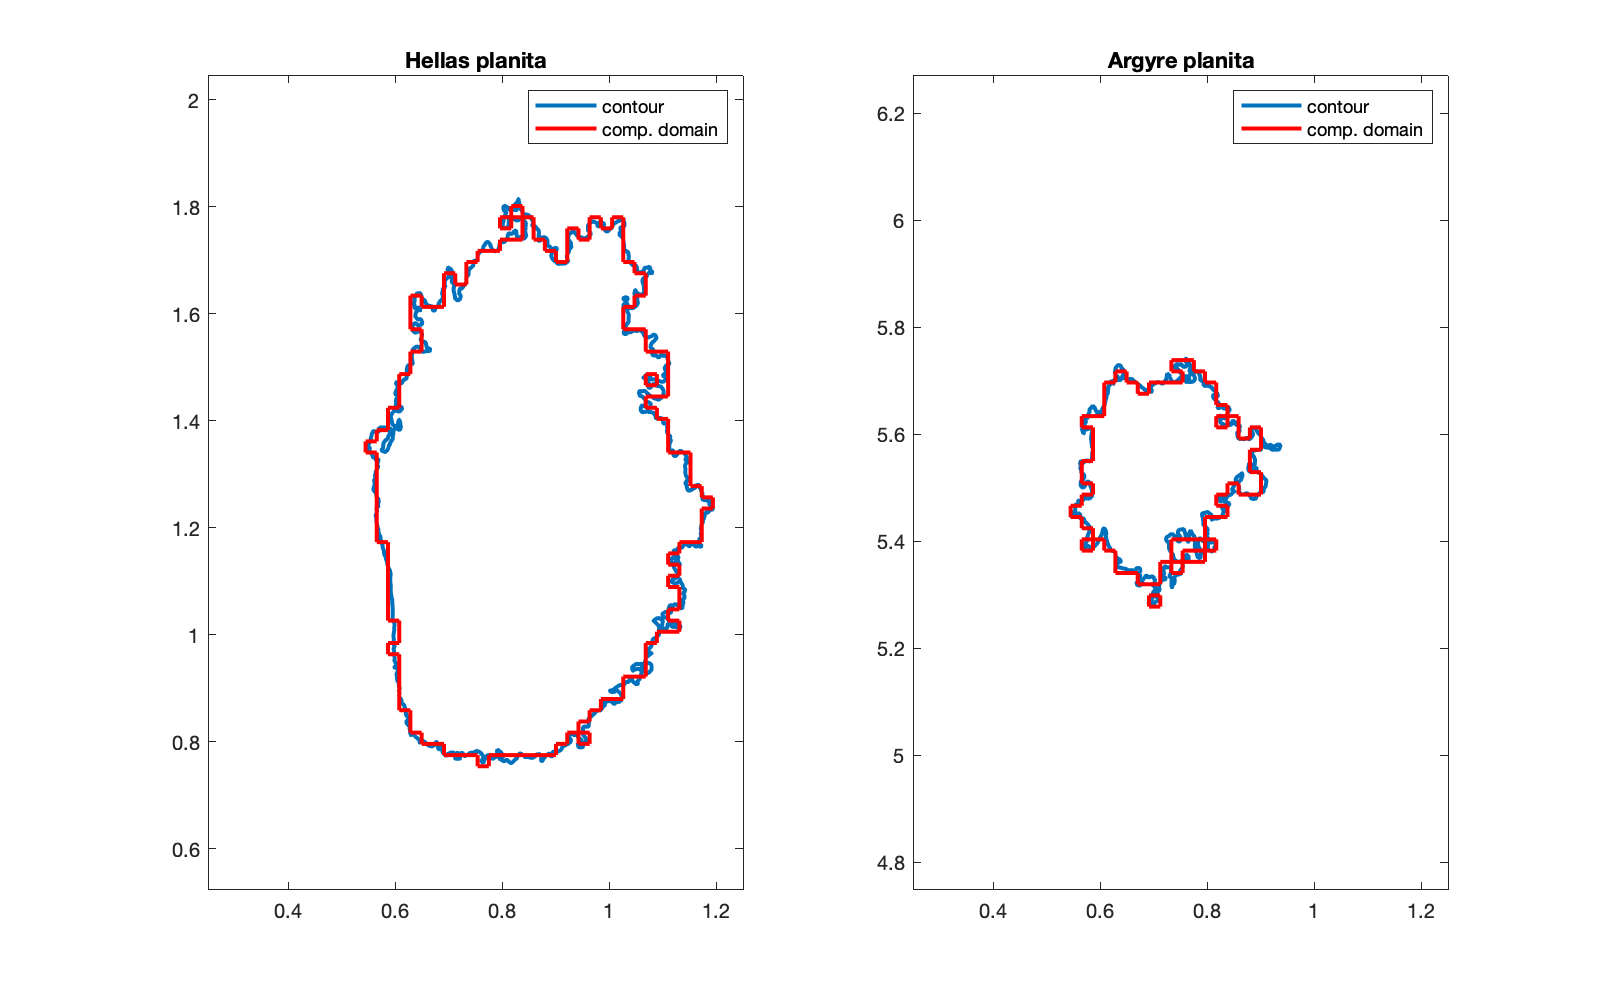

figure('position',[10 10 800 500])
subplot 121
plot(hellas.x,hellas.y,'linewidth',2), hold on
plot(X_f_hellas,Y_f_hellas,'r-','linewidth',2)
xlim([.25 1.25]), ylim([.5 2])
title 'Hellas planita'
axis equal
legend('contour','comp. domain')

subplot 122
plot(argyre.x,argyre.y,'linewidth',2), hold on
plot(X_f_argyre,Y_f_argyre,'r-','linewidth',2)
xlim([.25 1.25]), ylim([5 6])
title 'Argyre planita'
axis equal
legend('contour','comp. domain')

The dichotomy boundary is not a closed contour so we add the corners of the domain to it.

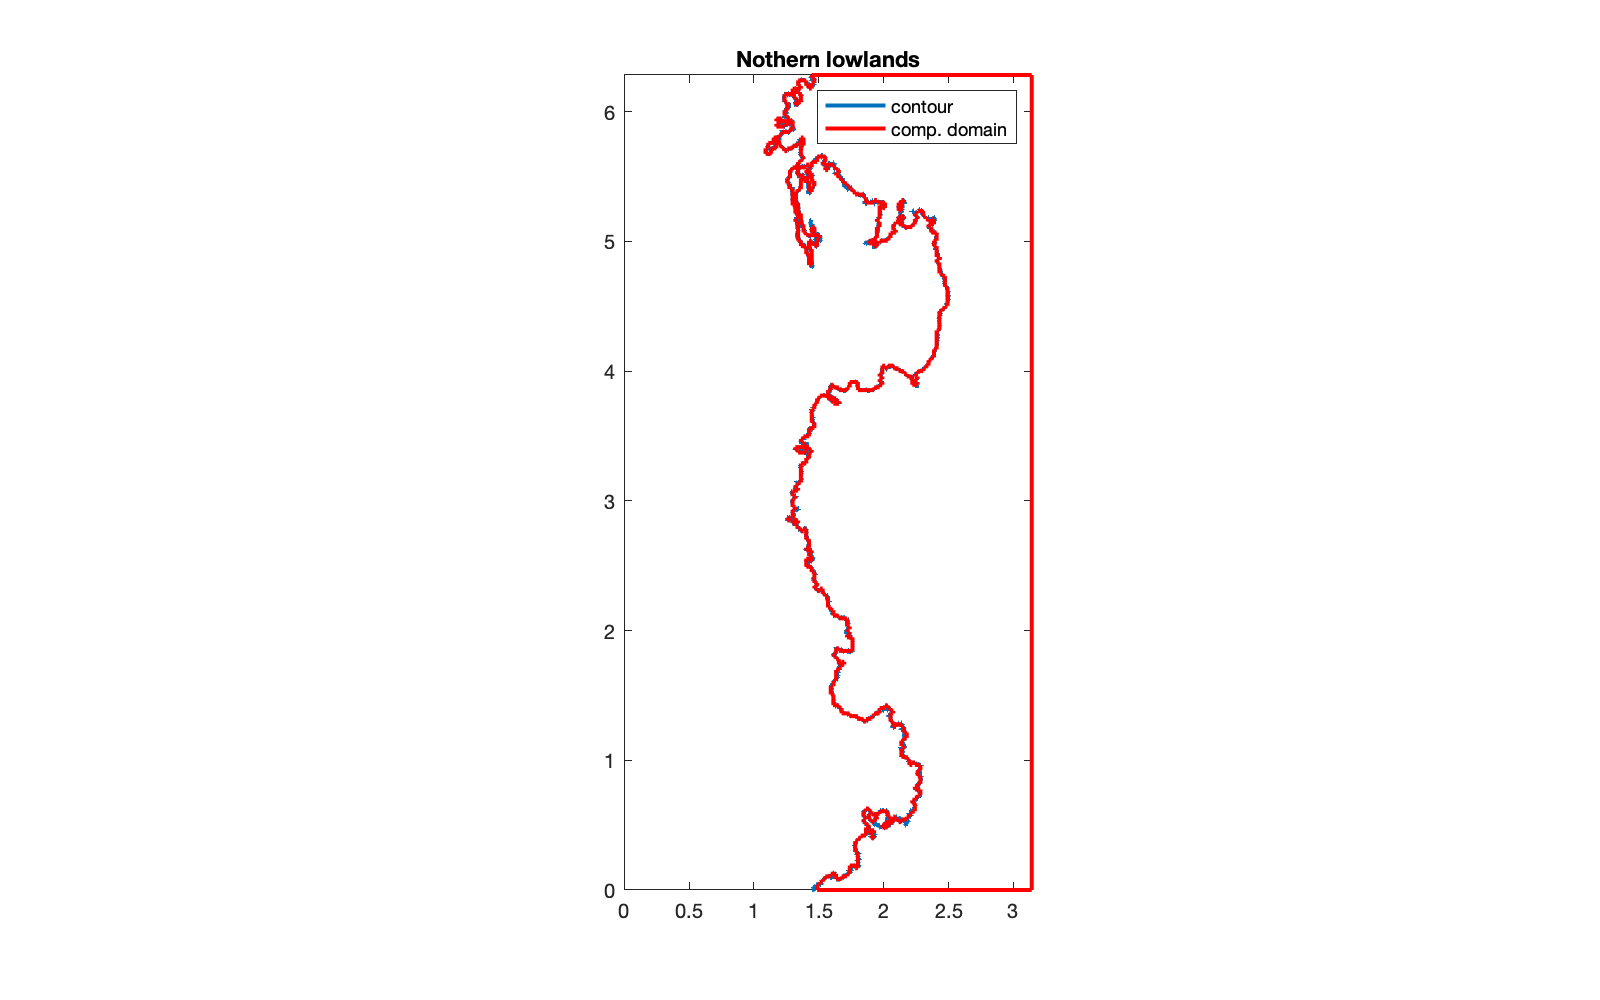

lowlands.x = [pi;cont(1).x;pi;pi];
lowlands.y = [0;cont(1).y;2*pi;0];

dof_lowlands = Grid.dof(inpolygon(Xc(:),Yc(:),lowlands.x,lowlands.y));
dof_f_lowlands = find_faces(dof_lowlands,Dref,Grid);
[X_f_lowlands,Y_f_lowlands] = comp_face_coords(dof_f_lowlands,Grid);

figure('position',[10 10 800 500])
plot(dichotomy.x,dichotomy.y,'linewidth',2), hold on
plot(X_f_lowlands,Y_f_lowlands,'r-','linewidth',2)
title 'Nothern lowlands'
axis equal
xlim([0 pi]), ylim([0 2*pi])
legend('contour','comp. domain')

In general the algorithm for finding the faces seems to work robustly, but there are some issues with isolated contours that are due to our grid not resolving the small embayments of the contours. This will need to be removed before we can use these boundaries for our computations.